# Pulse detector test bench (step 2)

© 2019-2020 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

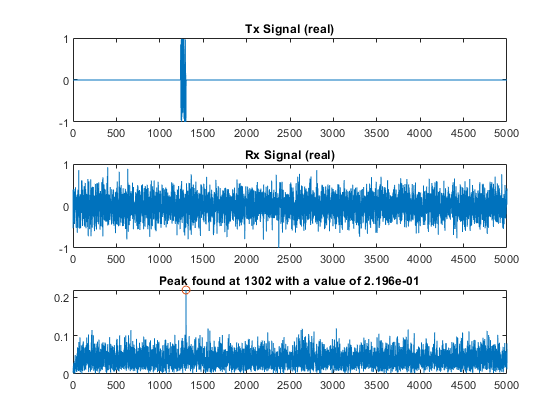

pulse_detector_reference;

## Simulate model and compare results to reference

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
slout = sim('sim1');

% Correlation filter output
FilterOutSL = getLogged(slout,'filter_out');
FilterValid = getLogged(slout,'filter_valid');
FilterOutSL = FilterOutSL(FilterValid);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 8.326673e-17 (absolute), 3.795220e-14 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 9.020562e-17 (absolute), 7.850267e-14 (percentage)


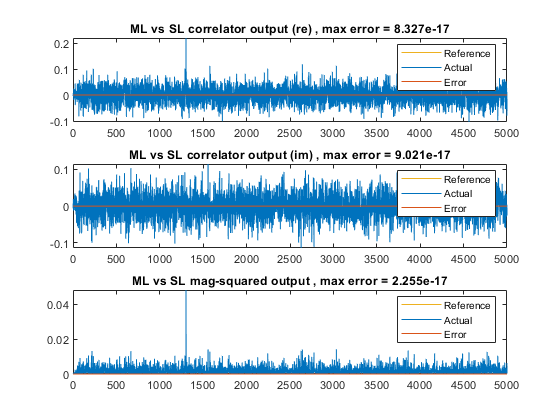


Maximum error for ML vs SL mag-squared output out of 5000 values
 2.255141e-17 (absolute), 4.676328e-14 (percentage)



% Magnitude squared output
MagSqSL = getLogged(slout,'mag_sq_out');
MagSqSL = MagSqSL(FilterValid);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = getLogged(slout,'mid_sample');
Detected = getLogged(slout,'detected');
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 1302, magnitude = 2.196e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 1302, mag-squared = 4.822e-02 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 4.822e-02, error = 2.082e-17


function signal_val = getLogged(simout_obj,signal_name)

logsout = simout_obj.logsout;
if isempty(logsout)
    error('No logged signal found. Make sure ''%s'' is logged in the model',...
        signal_name);
end

sig = logsout.getElement(signal_name);
if isempty(sig)
    error('Signal ''%s'' not found. Make sure it is logged and named correctly.',...
        signal_name);
end

signal_val = squeeze(sig.Values.Data);

end

function err_vec = compareData(reference,actual,figure_number,textstring)

% Vector input only
if ~isvector(reference) || ~isvector(actual)
    error('Input signals must be vector');
else
    if isrow(reference)
        reference = transpose(reference);
    end
    if isrow(actual)
        actual = transpose(actual);
    end
end

% Make signals same length if necessary
if length(reference) ~= length(actual)
%     warning(['Length of reference (%d) is not the same as actual signal (%d).'...
%         ' Truncating the longer input.'],length(reference),length(actual));
    len = 1:min(length(reference),length(actual));
    reference = reference(len);
    actual = actual(len);
end

% Turn complex into vector
if xor(isreal(reference),isreal(actual))
    error('Input signals are not both real or both complex');
elseif ~isreal(reference)
    ref_vec = double([real(reference) imag(reference)]);
    act_vec = double([real(actual) imag(actual)]);
    tag = {'(Real)','(Imag)'};
else
    ref_vec = double(reference);
    act_vec = double(actual);
    tag = {''};
end

% Configure figure
if iscell(figure_number)
    if size(ref_vec,2) > 1 % complex
        error('Cannot yet subplot multiple complex inputs');
    else
        figure(figure_number{1})
    end
else
    figure(figure_number)
end
c = get(groot,'defaultAxesColorOrder');

% Compute error
err_vec = ref_vec - act_vec;
max_err = max(abs(err_vec));
max_ref = max(abs(ref_vec));
fprintf('\nMaximum error for %s out of %d values\n',textstring,length(actual));


for n = 1:size(ref_vec,2)
    fprintf('%s %d (absolute), %d (percentage)\n',tag{n},max_err(n),max_err(n)/max_ref(n)*100);
    if iscell(figure_number)
        total_plot = figure_number{2};
        plot_num = figure_number{3};
    else
        total_plot = size(ref_vec,2);
        plot_num = n;
    end
    subplot(total_plot,1,plot_num)
    plot(ref_vec(:,n),'Color',c(3,:));
    hold on
    plot(act_vec(:,n),'Color',c(1,:));
    plot(err_vec(:,n),'Color',c(2,:));
    legend('Reference','Actual','Error')
    hold off
    title(sprintf('%s %s, max error = %.3d',textstring,tag{n},max_err(n)));
end
end